clearvars
load('cat_annotation.mat')
train = imread("cat_train.png");


size(xx)
size(yy)
size(train)
imshow(train)
hold on
point = plot(xx,yy,'o');
set(point,'LineWidth',3)
set(point,'MarkerSize',10)

% data = cat(2,xx,yy);
tform = randomAffine2d("YReflection",true,"Rotation",[-10 10],"XTranslation",[-50 50],"YTranslation",[-50 50],"Scale",[0.5 2]);
outputView = affineOutputView(size(train),tform,"BoundsStyle","SameAsInput");
train1 = imwarp(train,tform,OutputView=outputView);


tform2 = randomAffine2d("XReflection",true);
train2 = imwarp(train,tform2);


tform3 = randomAffine2d("Rotation",[-10 10],"YTranslation",[-50 50],"Scale",[0.5 2]);
train3 = imwarp(train,tform3,OutputView=outputView);


tform4 = randomAffine2d("Rotation",[-10 10],"XTranslation",[-50 50],"YTranslation",[-50 50]);
train4 = imwarp(train,tform4,OutputView=outputView);


tform5 = randomAffine2d("Rotation",[-10 10],"YTranslation",[-50 50]);
train5 = imwarp(train,tform5,OutputView=outputView, FillValues=[128 128 128]);


tform6 = randomAffine2d("Rotation",[-10 10],"Scale",[0.8 1]);
train6 = imwarp(train,tform6,OutputView=outputView);


tform7 = randomAffine2d("Rotation",[-45 45],"XTranslation",[-50 50],'YTranslation',[-50 50]);
train7 = imwarp(train,tform7,OutputView=outputView);



 imshow(train7)
 [x, y] = ginput

imwrite(train,'cat_1.png');
imwrite(train1,'cat_2.png');
imwrite(train2,'cat_3.png');
imwrite(train3,'cat_4.png');
imwrite(train4,'cat_5.png');
imwrite(train5,'cat_6.png');
imwrite(train6,'cat_7.png');
imwrite(train7,'cat_8.png');

% xandy1 = cat(2,x,y);
% xandy2 = cat(2,x,y);
% xandy3 = cat(2,x,y);
% xandy4 = cat(2,x,y);
% xandy5 = cat(2,x,y);
% xandy6 = cat(2,x,y);
% xandy7 = cat(2,x,y);
xxandyy = cat(2,xx,yy);
data = cat(3,xxandyy,xandy1,xandy2,xandy3,xandy4,xandy5,xandy6,xandy7);

y_train = cat(2,xxandyy,xandy1,xandy2,xandy3,xandy4,xandy5,xandy6,xandy7);
x_train = cat(4,train,train1,train2,train3,train4,train5,train6,train7);

% please = reshape(data,[8 5 2]); Icarus
leftear_xy = data(1,:,:);
leftear_xy = reshape(leftear_xy,[8 2]);
rightear_xy = data(2,:,:);
rightear_xy = reshape(rightear_xy,[8 2]);
lefteye_xy = data(3,:,:);
lefteye_xy = reshape(lefteye_xy,[8 2]);
righteye_xy = data(4,:,:);
righteye_xy = reshape(righteye_xy,[8 2]);
nose_xy = data(5,:,:);
nose_xy = reshape(nose_xy,[8 2]);


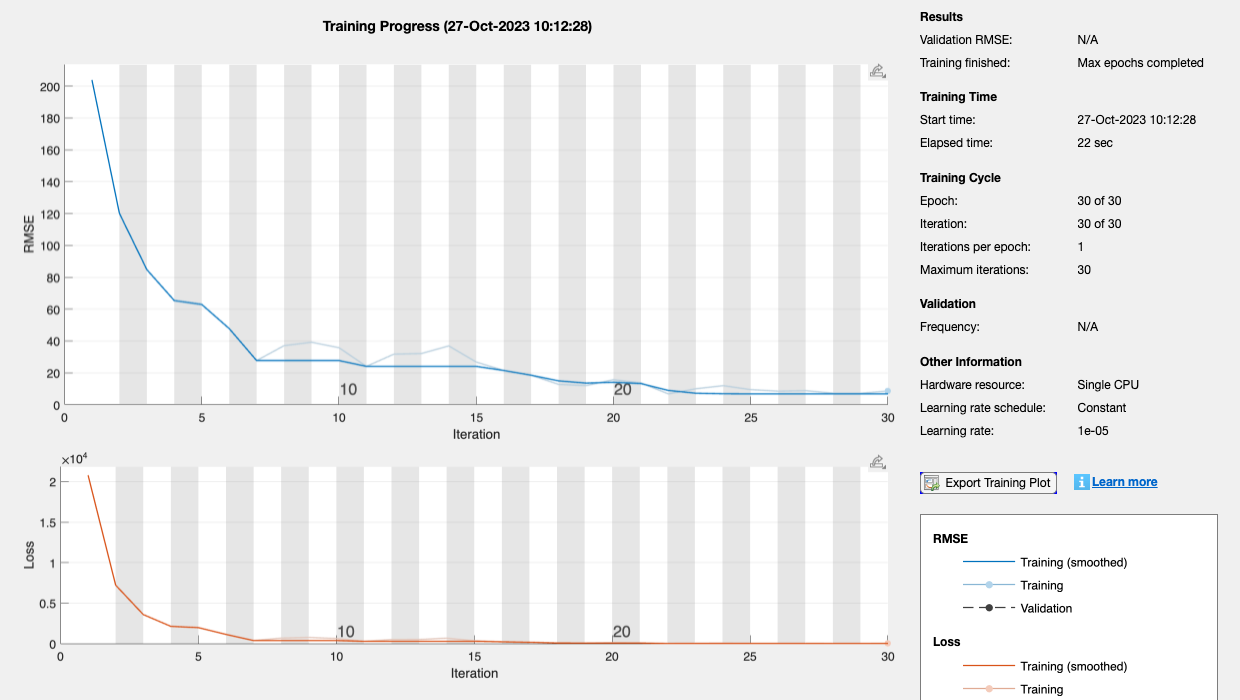

layers = [
    imageInputLayer([600 600 3])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(2)
    regressionLayer];


options = trainingOptions('sgdm', ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'InitialLearnRate',0.00001);
 net1 = trainNetwork(x_train,leftear_xy,layers,options);

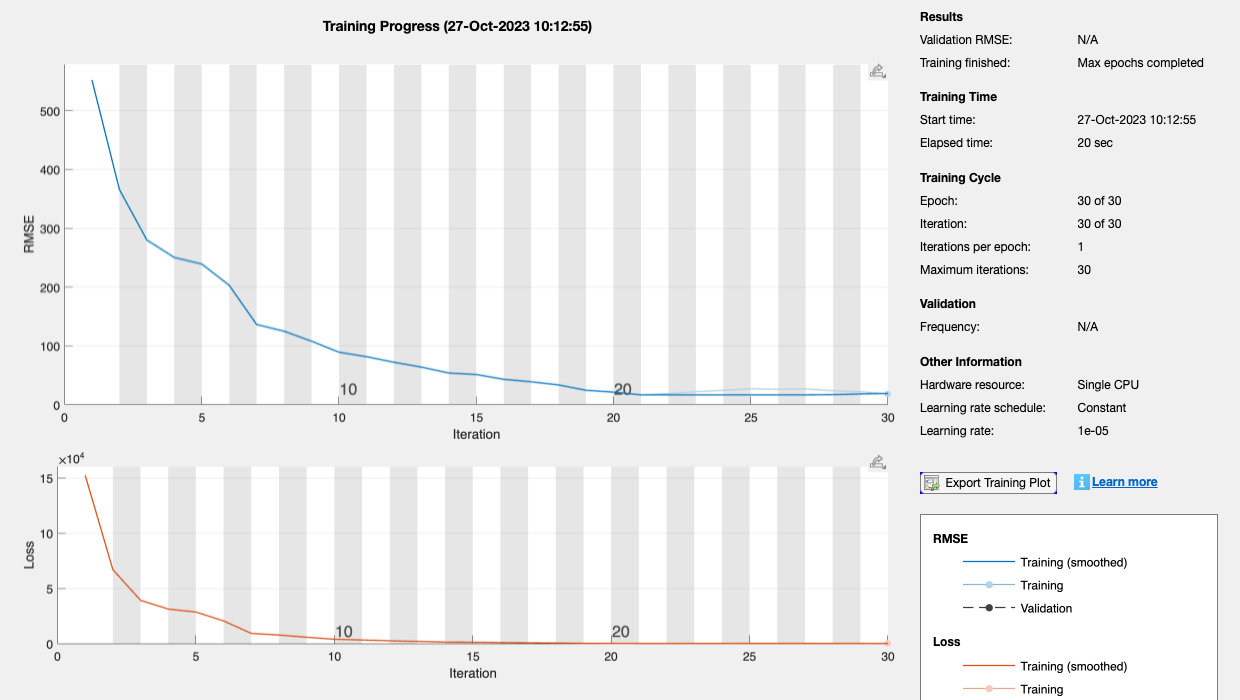

 net2 = trainNetwork(x_train,rightear_xy,layers,options);

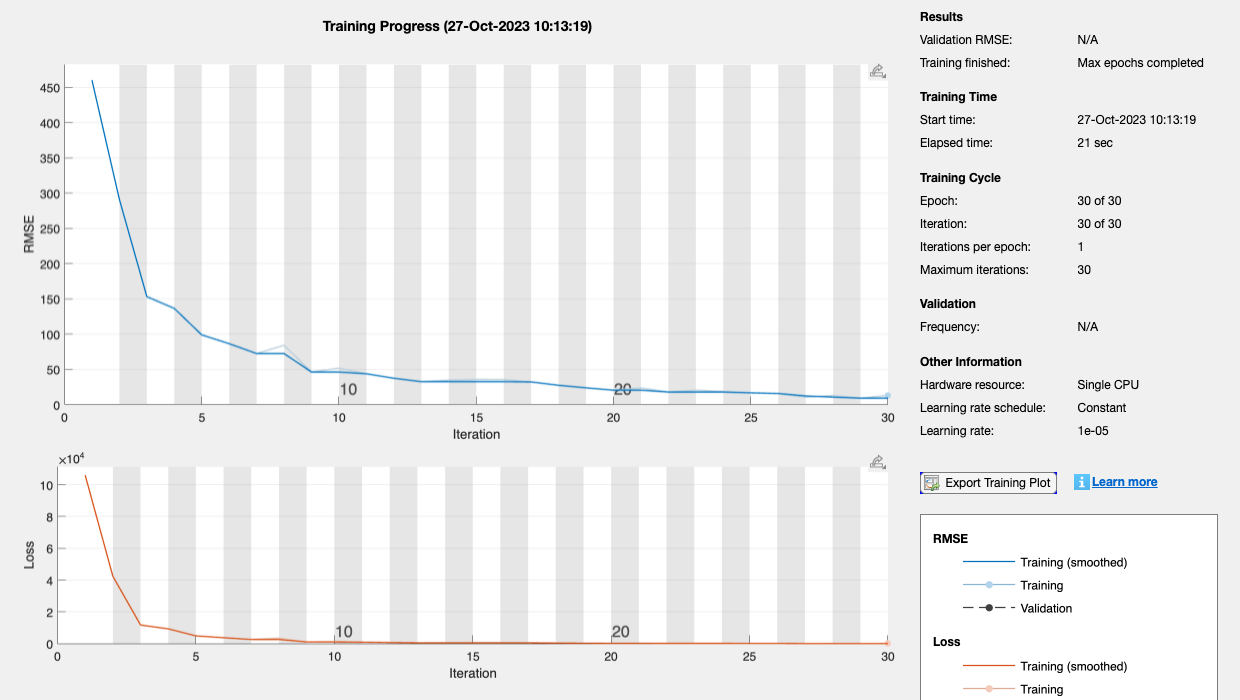

 net3 = trainNetwork(x_train,lefteye_xy,layers,options);

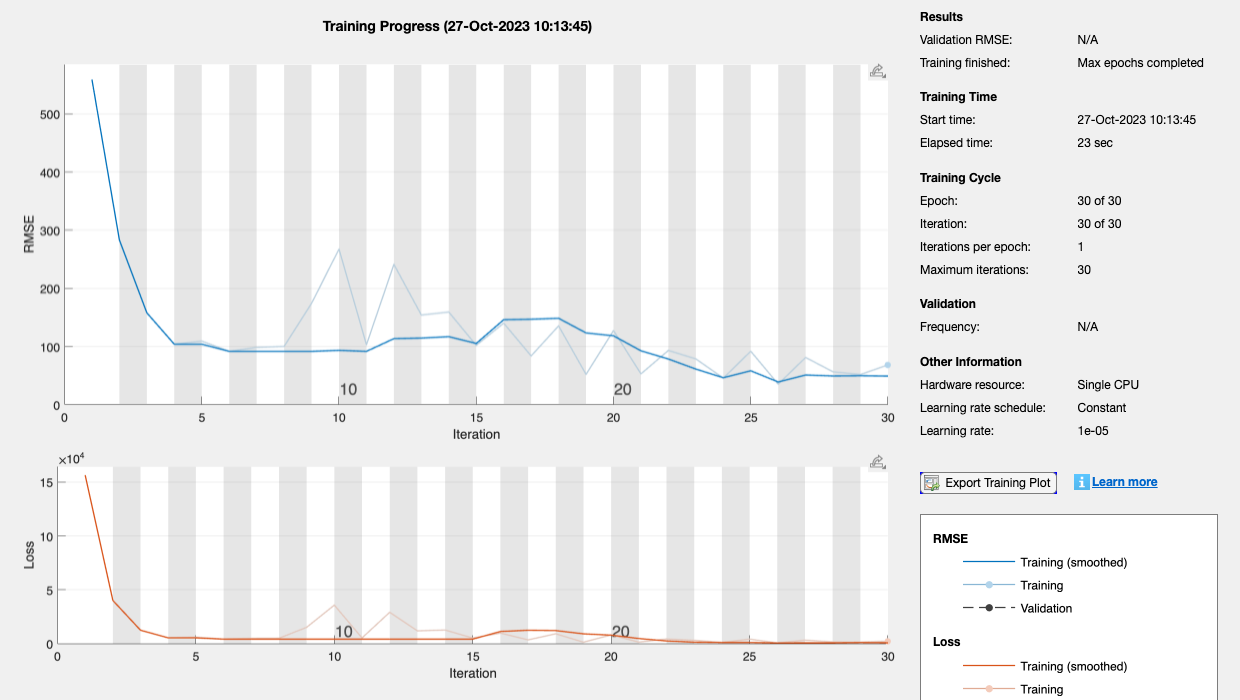

 net4 = trainNetwork(x_train,righteye_xy,layers,options);

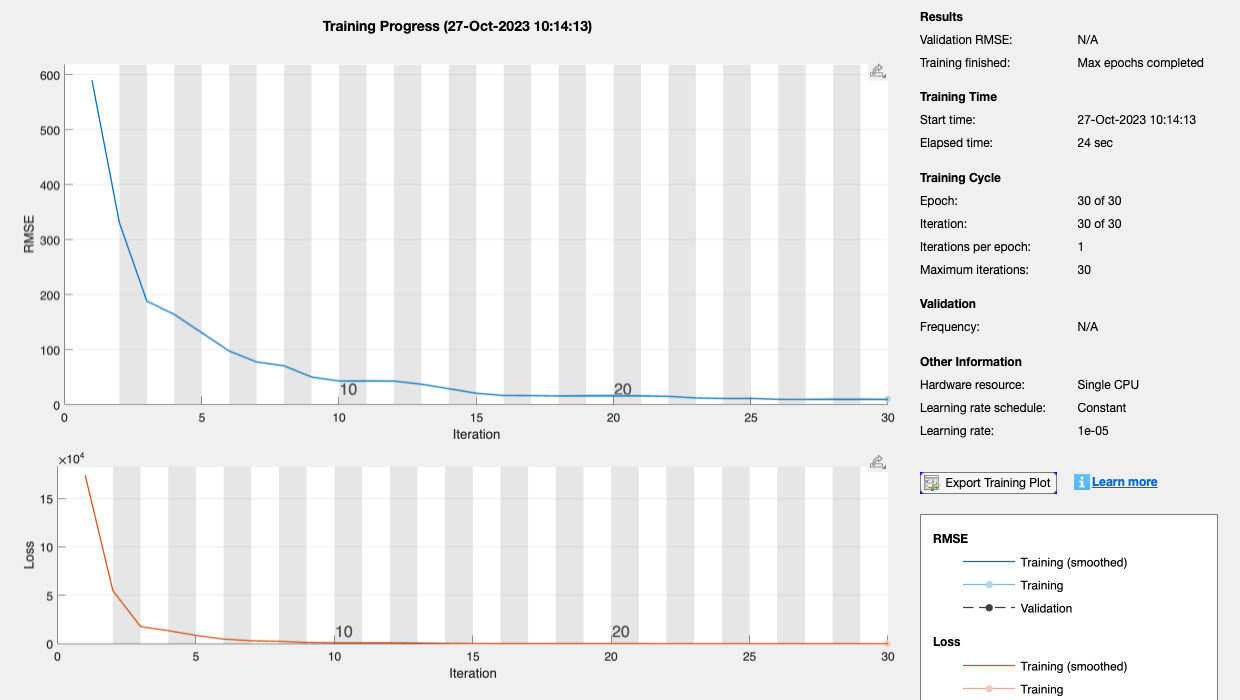

 net5 = trainNetwork(x_train,nose_xy,layers,options);

test = zeros(600,600,3,3);
for iii = 1:3
    test(:,:,:,iii) = double(imread(['cat_test' num2str(iii) '.png']));
end

leftear = predict(net1,test);
rightear = predict(net2,test);
lefteye = predict(net3,test);
righteye = predict(net4,test);
nose = predict(net5,test);
point_test = cell(1,3);
for i = 1:3
    point_test{i} = cat(1,leftear(i,:),rightear(i,:),lefteye(i,:),righteye(i,:),nose(i,:));
end

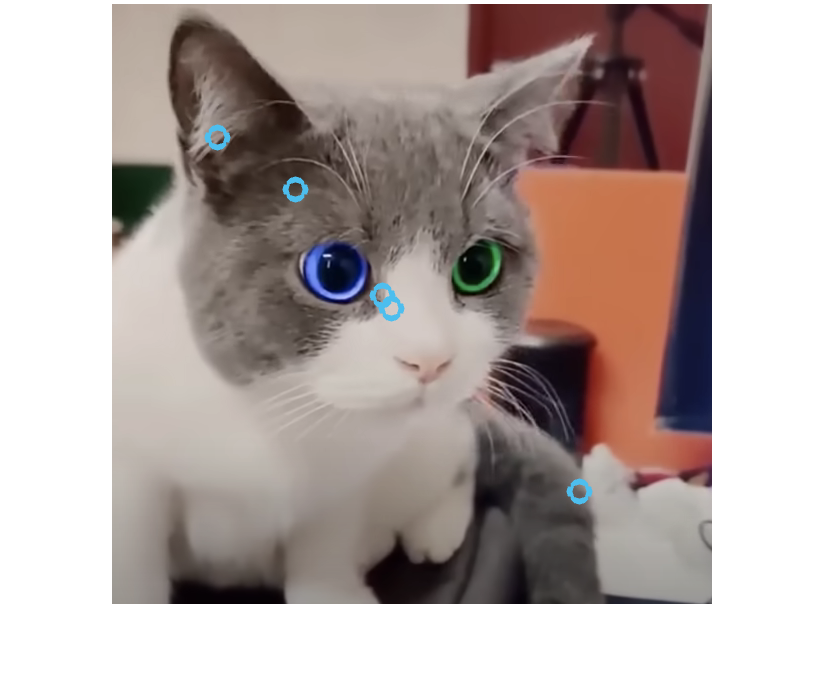

imshow(test(:,:,:,3)/255)
hold on
point = plot(point_test{3}(:,1),point_test{3}(:,2),'o');
set(point,'LineWidth',3)
set(point,'MarkerSize',10)